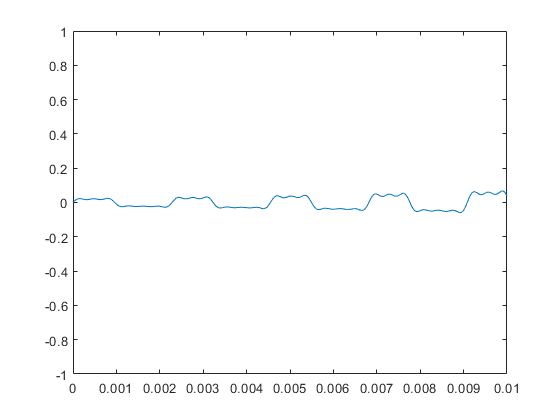

clear
% sampling rate
fs = 44100;
%time 5s
noteLength = 0.3;
%pitch of note
pitch = 440;

% VCO(freq,length,mode,ratio,fs)
% freq: basic pitch of the note
% length: time length of the note
% mode: wave form ['sin' 'sawtooth' 'triangle' 'square']
% ratio: duty ratio of ['sawtooth' 'square'] wave form
% fs: sampling frequency
note1 = VCO(pitch,noteLength,'square',0.42,fs);

% VCF(source,cutoff,resoAmp,resoLength,resoRatio,fs)
% source: source note generated from VCO
% length: time length of the note
% cutoff: cuttoff frequency of LPF
% resoAmp: ratio between the peak of cutoff to low frequency sounds (>1)
% resoLength: window length of the resonance in relative to cuttoff frequency
% resoRatio: ratio of the resonance window
% fs: sampling frequency
note1 = VCF(note1,noteLength,3000,1.2,0.3,0.8,fs);

% VCA(source,length,amp,attack,decay,sustain,release,fs)
% source: source note generated from VCF
% length: time length of the note
% amp: amplifier ratio of the note
% attack: attack time in ms
% decay: decya time in ms
% sustain: sustain level in ratio to 1
% release: release time in ms
% fs: sampling frequency
note1 = VCA(note1,noteLength,0.5,50,150,0.8,100,fs);

%plot
plot(0:1/fs:noteLength-1/fs,note1);
xlim([0 0.01])
ylim([-1 1])

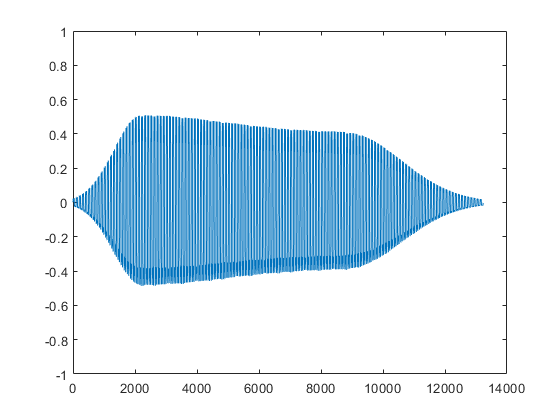

plot(note1)
ylim([-1 1])


%play audio
% chirpObj = audioplayer(note1,fs);
% play(chirpObj)
sound(note1,fs);

clear

fs = 2e3;
t = 0:1/fs:0.25-1/fs;

l = [0 130.81 146.83 164.81 174.61 196.00 220 246.94];
m = [0 261.63 293.66 329.63 349.23 392.00 440 493.88];
h = [0 523.25 587.33 659.25 698.46 783.99 880 987.77];
note = @(f,g) [1 1 1]*sin(2*pi*[l(g) m(g) h(f)]'.*t);

mel = [3 2 1 2 3 3 3 0 2 2 2 0 3 5 5 0 3 2 1 2 3 3 3 3 2 2 3 2 1]+1;
acc = [3 0 5 0 3 0 3 3 2 0 2 2 3 0 5 5 3 0 5 0 3 3 3 0 2 2 3 0 1]+1;

song = [];
for kj = 1:length(mel)
    song = [song note(mel(kj),acc(kj)) zeros(1,0.01*fs)];
end
song = song/(max(abs(song))+0.5);

sound(song,fs)

clear

fs = 44100;
len = 0.25;

l = [0 130.81 146.83 164.81 174.61 196.00 220 246.94];
m = [0 261.63 293.66 329.63 349.23 392.00 440 493.88];
h = [0 523.25 587.33 659.25 698.46 783.99 880 987.77];

% marry has a little lamb
% mel = [3 2 1 2 3 3 3 0 2 2 2 0 3 5 5 0 3 2 1 2 3 3 3 3 2 2 3 2 1]+1;
% acc = [3 0 5 0 3 0 3 3 2 0 2 2 3 0 5 5 3 0 5 0 3 3 3 0 2 2 3 0 1]+1;
% accl = [3 0 5 0 3 0 3 3 2 0 2 2 3 0 5 5 3 0 5 0 3 3 3 0 2 2 3 0 1]+1;

%Original that feels like supermarket commercial song
mel = [5 5 0 5 4 3 0 3 3 0 2 2 0 0 3 5 4 3 3 2 0 1 1 3 2 2 0 4 0 3 2 1]+1;
acc = [1 0 3 0 5 0 3 0 2 0 5 0 7 0 5 0 1 0 3 0 6 0 3 0 1 0 4 0 6 0 1 0]+1;
accl = [1 1 0 1 3 3 0 1 2 2 0 2 5 5 0 2 3 3 0 3 6 6 0 3 4 4 0 4 1 1 0 1]+1;

song = [];
for kj = 1:length(mel)
    note = [1 1 1]*[0.7*SynthOne(l(accl(kj)),len,fs);0.5*SynthOne(m(acc(kj)),len,fs);0.9*SynthTwo(h(mel(kj)),len,fs)];
    song = [song note];
end

song = song/3;
song = [song zeros(1,fs*0.2)];

sound(song,fs)
% audiowrite('SynthOne.wav',song,fs);

**Synth1**

**A preset that generate a synth note**

**Kind of like the sound of an oboe**

function note = SynthOne(pitch, noteLength, fs)

note = VCO(pitch,noteLength,'square',0.42,fs);
note = VCF(note,noteLength,1200,1.2,0.3,0.8,fs);
note = VCA(note,noteLength,0.4,50,50,0.8,50,fs);

end

**Synth2**

**Another preset**

function note = SynthTwo(pitch, noteLength, fs)

note = VCO(pitch,noteLength,'sawtooth',0.42,fs);
note = VCF(note,noteLength,3200,1.2,0.3,0.8,fs);
note = VCA(note,noteLength,0.5,50,50,0.8,50,fs);

end

**Voltage Controlled Oscillator**

function note = VCO(freq,length,mode,ratio,fs)

t = 0:1/fs:length-1/fs;
switch mode
    case 'sin'
        %sin
        note = sin(2*pi*freq*t);
    case 'sawtooth'
        %Sawtooth
        note = sawtooth(2*pi*freq*t, ratio);
    case 'triangle'
        %Triangle
        note= sawtooth(2*pi*freq*t, 0.5);
    case 'square'
        %Square
        note = square(2*pi*freq*t,ratio*100);
end

end

**Voltage Controlled Filter**

function note = VCF(source,length,cutoff,resoAmp,resoLength,resoRatio,fs)

%make a lpf with resonance window
resoMultiPlier = 1/resoAmp;
resoLength = length*cutoff*resoLength;
win1 = tukeywin(resoLength,resoRatio);
win1 = win1(1:round(0.5*resoLength))'*(1-resoMultiPlier)+resoMultiPlier;
win2 = tukeywin(resoLength,resoRatio);
win2 = win2(round(0.5*resoLength)+1:end)';
filterhalf = [ones(1, floor((length*cutoff)-0.5*resoLength))*resoMultiPlier win1 win2 zeros(1, ceil(length*(0.5*fs-cutoff)-0.5*resoLength))];
lpFilter = [filterhalf flip(filterhalf)];

%apply the filter to the source
notefft = fft(source);
lpnotefft = notefft.*lpFilter(1:width(notefft));
note = real(ifft(lpnotefft));

end

**Voltage Controlled Amplifier**

function note = VCA(source,length,amp,attack,decay,sustain,release,fs)

attackIndex = round(fs*attack/1e3);
decayIndex = round(fs*decay/1e3);
releaseIndex = round(fs*release/1e3);
sustainIndex = round(fs*length)-attackIndex-decayIndex-releaseIndex;

attackWin = gausswin(2*attackIndex);
attackWin = attackWin(1:attackIndex)';
decayWin = gausswin(2*decayIndex);
decayWin = decayWin(decayIndex+1:end)'*(1-sustain)+sustain;
releaseWin = gausswin(2*releaseIndex);
releaseWin = releaseWin(releaseIndex+1:end)'*sustain;

envelopeG = [attackWin decayWin sustain*ones(1,sustainIndex) releaseWin];
note = source.*envelopeG*amp;

end